## do megastats

## ROI x color x shape interaction with rm ANOVA (disregarding congruency!)

%% readfiles
% 
cd /Users/k.siudakrzywicka/Desktop/RDS_fMRI/Controls/colorRegions_rois/from_secondLevel_peaks/color-regions-p001corr/final/8mmspheres/

megaTable=readtable('megaTable_bin_best_50vox_spmT_0001_confiles.csv');

%% stats

ROI = cell(1,40);
k = regexp(megaTable.Properties.VariableNames, '_', 'once');
idx = [k{:}]';

for n = 1:length(idx)
    ROI{n} = megaTable.Properties.VariableNames{n}(1:idx(n)-1);
end


CS_megaTable = megaTable(:, ~contains(megaTable.Properties.VariableNames, 'wrong'));
CS_ROI = ROI(logical(repmat([0 0 1 1 1 1 1 1 1 1]', 4, 1)))';

CS_ROI = categorical(CS_ROI);
side = categorical(reshape(repmat({'left', 'right'}, 4,4), [],1));
shape = repmat([1 1 0 0]', 8, 1);
color = repmat([1 0 1 0]', 8, 1);


CS_within_factor = table(CS_ROI, side, shape, color,...
    'VariableNames', {'ROI', 'Side', 'Shape', 'Color'});

CS_rm = fitrm(CS_megaTable,'anteriorFusiform_left_object_good_color-occipitalFusiform_right_mondirans_grey_scale~1',...
    'WithinDesign',CS_within_factor);
[CS_rm_anova_results] = ranova(CS_rm, 'WithinModel','ROI*Side*Shape*Color')

CS_rm_anova_results = 32×8 table
                              SumSq     DF    MeanSq      F         pValue       pValueGG      pValueHF      pValueLB 
                              ______    __    ______    ______    __________    __________    __________    __________

    (Intercept)               2056.8     1    2056.8    344.15    1.2436e-13    1.2436e-13    1.2436e-13    1.2436e-13
    Error                     113.55    19    5.9763         1           0.5           0.5           0.5           0.5
    (Intercept):ROI           35.529     3    11.843    5.1017     0.0033861     0.0058717     0.0036045      0.035853
    Error(ROI)                1



CS_long_form = stack(CS_megaTable, CS_megaTable.Properties.VariableNames, 'IndexVariableName','Conditions',...
    'NewDataVariableName','Response');

CS_marg_means = margmean(CS_rm, {'ROI', 'Side', 'Shape', 'Color'} )

CS_marg_means = 32×8 table
          ROI           Side     Shape    Color     Mean     StdErr      Lower     Upper 
    ________________    _____    _____    _____    ______    _______    _______    ______

    anteriorFusiform    left     0        0        1.2927    0.20728     0.8589    1.7266
    anteriorFusiform    left     0        1        1.4935    0.23454     1.0026    1.9844
    anteriorFusiform    left     1        0        1.9952    0.25615     1.4591    2.5313
    anteriorFusiform    left     1        1        2.0918    0.23649     1.5969    2.5868
    anteriorFusiform    right    0        0        1.1276    0.15967    0.79342    1.4618
    anteriorFusiform    right    0        1        1.2143    0.14979  

## plot margmeans

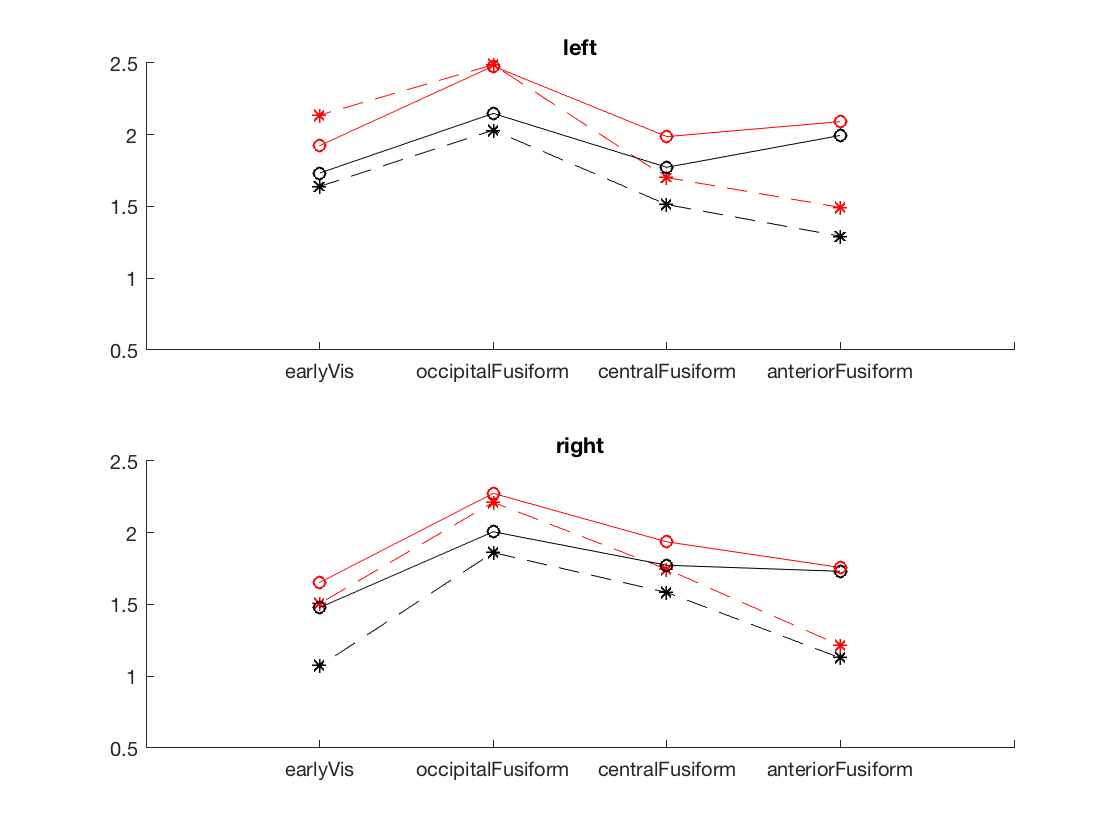

figure

Marker = {'--*', '--*', '-o','-o'};
Color = {'k', 'r', 'k', 'r'};
for i = 1:height(CS_marg_means)/4
    
    data = CS_marg_means(i:8:end, :);
    data = data([3,4,2,1], :);
    if i < 5  
        subplot(2,1,1);
        marker_idx = i;
        
    else
        subplot(2,1,2);
        marker_idx = i-4;
    end
    
    hold on
    plot(data{:,5}, Marker{marker_idx}, 'Color', Color{marker_idx})
%     hold on
%     er = errorbar(data{:,5}, data{:,6}, Marker{marker_idx}, 'Color', Color{marker_idx})
%     er.LineStyle = 'none';
    xlim([0 5]);
    ylim ([0.5 2.5])
    xticks(1:1:5);
    xticklabels(string(data{:,1}));
    title(string(data.Side(1)))
    hold off
    
    
end

## do post-hoc

%%%%% FIGURE OUT %%%%%

## ROI x congruency interaction

Congr_megaTable = megaTable(:, contains(megaTable.Properties.VariableNames, 'wrong')|contains(megaTable.Properties.VariableNames, 'good'));

ROI_congr = sort(repmat(unique(CS_ROI), 4,1));
side_congr = repmat(side(1:4:end), 2,1);
congr = repmat([0 0 1 1]', 4, 1);

Congr_within_factor = table(ROI_congr, side_congr, congr, 'VariableNames', {'ROI', 'Side', 'Congruency'});

Congr_rm = fitrm(Congr_megaTable,'anteriorFusiform_left_object_wrong_color-occipitalFusiform_right_object_good_color~1',...
    'WithinDesign',Congr_within_factor)

Congr_rm =   RepeatedMeasuresModel with properties:

   Between Subjects:
         BetweenDesign: [20×16 table]
         ResponseNames: {1×16 cell}
    BetweenFactorNames: {1×0 cell}
          BetweenModel: '1'

   Within Subjects:
          WithinDesign: [16×3 table]
     WithinFactorNames: {'ROI'  'Side'  'Congruency'}
           WithinModel: 'separatemeans'

   Estimates:
          Coefficients: [1×16 table]
            Covariance: [16×16 table]


[Congr_rm_anova_results] = ranova(Congr_rm, 'WithinModel','ROI*Side*Congruency')

Congr_rm_anova_results = 16×8 table
                                         SumSq      DF     MeanSq         F          pValue       pValueGG      pValueHF      pValueLB 
                                       _________    __    _________    ________    __________    __________    __________    __________

    (Intercept)                           1294.1     1       1294.1      368.22    6.7498e-14    6.7498e-14    6.7498e-14    6.7498e-14
    Error                                 66.773    19       3.5144                                                                    
    (Intercept):ROI                       16.248     3       5.4161      3.9107      0.013097   

Congr_marg_means = margmean(Congr_rm, {'ROI', 'Side', 'Congruency'} )

Congr_marg_means = 16×7 table
           ROI           Side     Congruency     Mean     StdErr     Lower     Upper 
    _________________    _____    __________    ______    _______    ______    ______

    anteriorFusiform     left     0             2.2148    0.25941    1.6719    2.7578
    anteriorFusiform     left     1             1.8552    0.19923    1.4382    2.2722
    anteriorFusiform     right    0             2.0918    0.23649    1.5969    2.5868
    anteriorFusiform     right    1             1.7577    0.18212    1.3765    2.1389
    centralFusiform      left     0             1.9574     0.1845    1.5712    2.3435
    centralFusiform      left     1             1.9959      0.185    1.6087    2.3831
    centralFusiform      right    0        

## plot congruency anova

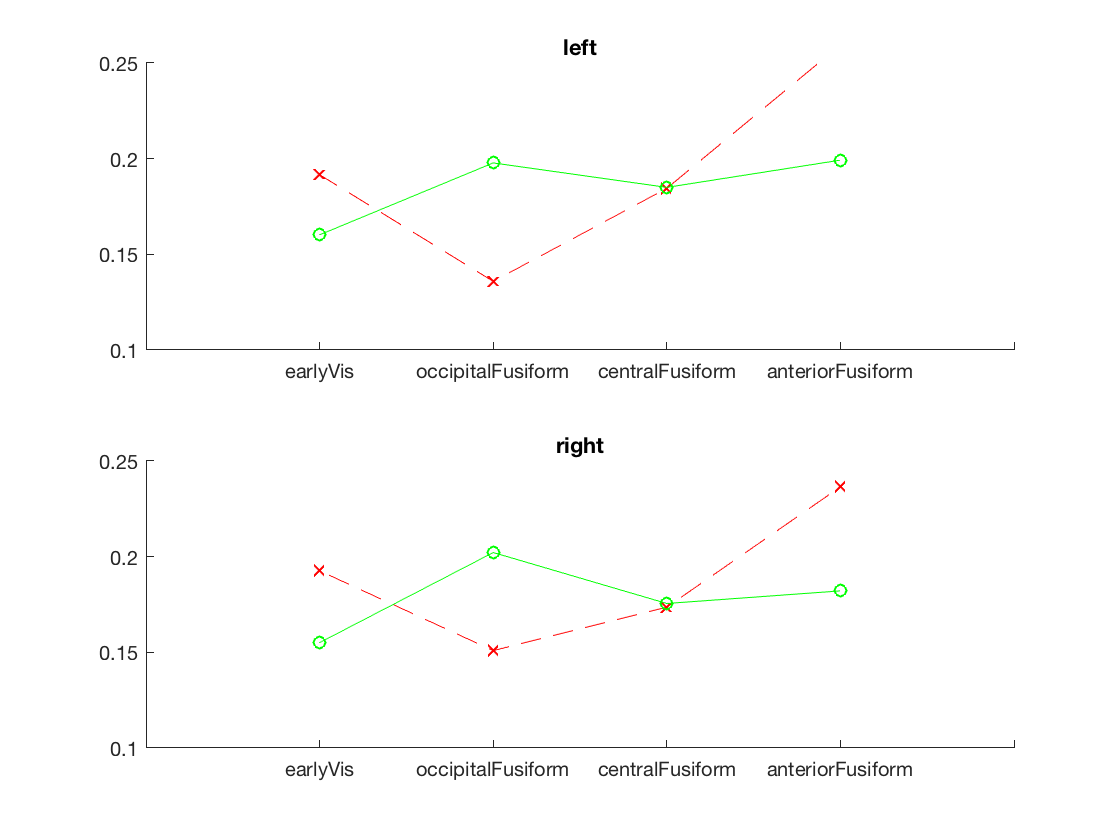

figure

Marker = {'--X','-o'};
Color = {'r', 'g'};

for i = 1:height(Congr_marg_means)/4
    
    data = Congr_marg_means(i:4:end, :);
    data = data([3,4,2,1], :);
    if i < 3  
        subplot(2,1,1);
        marker_idx = i;
        
    else
        subplot(2,1,2);
        marker_idx = i-2;
    end
    
    hold on
    plot(data{:,5}, Marker{marker_idx}, 'Color', Color{marker_idx})
%     hold on
%     er = errorbar(data{:,5}, data{:,6}, Marker{marker_idx}, 'Color', Color{marker_idx})
%     er.LineStyle = 'none';
    xlim([0 5]);
    ylim ([0.1 0.25])
    xticks(1:1:5);
    xticklabels(string(data{:,1}));
    title(string(data.Side(1)))
    hold off
    
    
end

## SIDE x ROI xCONDITION interaction 

## 1) WITH RM ANOVA

megaTable_long_form = stack(megaTable, megaTable.Properties.VariableNames(1:end), 'IndexVariableName','Conditions',...
    'NewDataVariableName','Response');

cond_parts = cellfun(@(x) strsplit(x, '_'), string(megaTable_long_form.Conditions), 'UniformOutput', 0);

megaTable_long_form.ROI = cellfun(@(x) x(1),  cond_parts);
megaTable_long_form.Side = cellfun(@(x) x(2),  cond_parts);
megaTable_long_form.Conditions =  cellfun(@(x) strjoin(x(3:end),'-'), cond_parts, 'UniformOutput', 0);
megaTable_long_form = megaTable_long_form(:, [ 4, 3, 1, 2]);

fullModel_within_factors = megaTable_long_form(1:40, 1:3);

full_rm = fitrm(megaTable,'anteriorFusiform_left_object_wrong_color-occipitalFusiform_right_mondirans_grey_scale~1',...
    'WithinDesign',fullModel_within_factors)

full_rm =   RepeatedMeasuresModel with properties:

   Between Subjects:
         BetweenDesign: [20×40 table]
         ResponseNames: {1×40 cell}
    BetweenFactorNames: {1×0 cell}
          BetweenModel: '1'

   Within Subjects:
          WithinDesign: [40×3 table]
     WithinFactorNames: {'Side'  'ROI'  'Conditions'}
           WithinModel: 'separatemeans'

   Estimates:
          Coefficients: [1×40 table]
            Covariance: [40×40 table]


[full_rm_anova_results] = ranova(full_rm, 'WithinModel','Side*ROI*Conditions')

full_rm_anova_results = 16×8 table
                                        SumSq     DF      MeanSq       F         pValue       pValueGG      pValueHF      pValueLB 
                                       _______    ___    ________    ______    __________    __________    __________    __________

    (Intercept)                         2696.5      1      2696.5    350.46    1.0556e-13    1.0556e-13    1.0556e-13    1.0556e-13
    Error                               146.19     19      7.6944                                                                  
    (Intercept):Side                    8.6575      1      8.6575    2.6798       0.11808       0.11808       0.1

post_hoc = multcompare(full_rm, 'Conditions', 'by', 'ROI');
post_hoc(post_hoc.pValue<0.05, :)

ans = 50×8 table
           ROI                 Conditions_1              Conditions_2         Difference     StdErr       pValue       Lower        Upper  
    __________________    ______________________    ______________________    __________    ________    __________    ________    _________

    'anteriorFusiform'    'mondirans-grey-scale'    'object-good-color'        -0.7146      0.096183    4.4859e-06     -1.0038     -0.42536
    'anteriorFusiform'    'mondirans-grey-scale'    'object-grey-scale'       -0.65308       0.11809    0.00021415     -1.0082     -0.29795
    'anteriorFusiform'    'mondirans-grey-scale'    'object-wrong-color'      -0.82481       0.10888    3.3959e-06     -1.1522      -0.4974
    'anter


% try with Roi and Side as an apriori interaction factor, see 
% https://fr.mathworks.com/matlabcentral/answers/140799-3-way-repeated-measures-anova-pairwise-comparisons-using-multcompare

fullModel_within_factors2 = fullModel_within_factors;
fullModel_within_factors2.ROI = categorical (fullModel_within_factors2.ROI);
fullModel_within_factors2.Side = categorical(fullModel_within_factors2.Side);
fullModel_within_factors2.Conditions = categorical(fullModel_within_factors2.Conditions);
fullModel_within_factors2.Side_x_ROI = fullModel_within_factors2.Side.*fullModel_within_factors2.ROI;
fullModel_within_factors2.ROI_x_Condition = fullModel_within_factors2.ROI.*fullModel_within_factors2.Conditions;

full_rm2 = fitrm(megaTable,'anteriorFusiform_left_object_wrong_color-occipitalFusiform_right_mondirans_grey_scale~1',...
    'WithinDesign',fullModel_within_factors2)

full_rm2 =   RepeatedMeasuresModel with properties:

   Between Subjects:
         BetweenDesign: [20×40 table]
         ResponseNames: {1×40 cell}
    BetweenFactorNames: {1×0 cell}
          BetweenModel: '1'

   Within Subjects:
          WithinDesign: [40×5 table]
     WithinFactorNames: {'Side'  'ROI'  'Conditions'  'Side_x_ROI'  'ROI_x_Condition'}
           WithinModel: 'separatemeans'

   Estimates:
          Coefficients: [1×40 table]
            Covariance: [40×40 table]



[full_rm2_anova_results] = ranova(full_rm2, 'WithinModel','Side*ROI*Conditions')

full_rm2_anova_results = 16×8 table
                                        SumSq     DF      MeanSq       F         pValue       pValueGG      pValueHF      pValueLB 
                                       _______    ___    ________    ______    __________    __________    __________    __________

    (Intercept)                         2696.5      1      2696.5    350.46    1.0556e-13    1.0556e-13    1.0556e-13    1.0556e-13
    Error                               146.19     19      7.6944                                                                  
    (Intercept):Side                    8.6575      1      8.6575    2.6798       0.11808       0.11808       0.

post_hoc_full_rm2_cond_by_ROIxSide = multcompare(full_rm2,'Conditions','By','Side_x_ROI');
post_hoc_full_rm2_cond_by_ROIxSide (post_hoc_full_rm2_cond_by_ROIxSide.pValue<0.05, :)

ans = 90×8 table
         Side_x_ROI              Conditions_1            Conditions_2        Difference     StdErr       pValue        Lower        Upper   
    _____________________    ____________________    ____________________    __________    ________    __________    _________    __________

    left anteriorFusiform    mondirans-grey-scale    object-good-color        -0.7991       0.11826    1.6749e-05      -1.1547      -0.44348
    left anteriorFusiform    mondirans-grey-scale    object-grey-scale       -0.70247       0.14892     0.0012545      -1.1503      -0.25464
    left anteriorFusiform    mondirans-grey-scale    object-wrong-color      -0.92209       0.13411    1.3225e-05      -1.3254      -0.51879
    l

post_hoc_full_rm2_Side_by_ROIxcond = multcompare(full_rm2,'Side','By','ROI_x_Condition');
post_hoc_full_rm2_Side_by_ROIxcond (post_hoc_full_rm2_Side_by_ROIxcond.pValue<0.05, :)

ans = 4×8 table
           ROI_x_Condition           Side_1    Side_2    Difference    StdErr      pValue      Lower        Upper  
    _____________________________    ______    ______    __________    _______    ________    ________    _________

    earlyVis mondirans-grey-scale    left      right      0.56814      0.22601    0.021119    0.095086       1.0412
    earlyVis mondirans-grey-scale    right     left      -0.56814      0.22601    0.021119     -1.0412    -0.095086
    earlyVis mondrian-color          left      right      0.63029      0.22549    0.011543     0.15834       1.1022
    earlyVis mondrian-color          right     left      -0.63029      0.22549    0.011543     -1.1022     -0.15834


## plot

full_rm2_margmeans = margmean(full_rm2,{'ROI','Side', 'Conditions'})

full_rm2_margmeans = 40×7 table
          ROI           Side          Conditions          Mean     StdErr      Lower     Upper 
    ________________    _____    ____________________    ______    _______    _______    ______

    anteriorFusiform    left     mondirans-grey-scale    1.2927    0.20728     0.8589    1.7266
    anteriorFusiform    left     mondrian-color          1.4935    0.23454     1.0026    1.9844
    anteriorFusiform    left     object-good-color       2.0918    0.23649     1.5969    2.5868
    anteriorFusiform    left     object-grey-scale       1.9952    0.25615     1.4591    2.5313
    anteriorFusiform    left     object-wrong-color      2.2148    0.25941     1.6719    2.7578
    anteriorFusiform    right    mondirans-grey-scale    

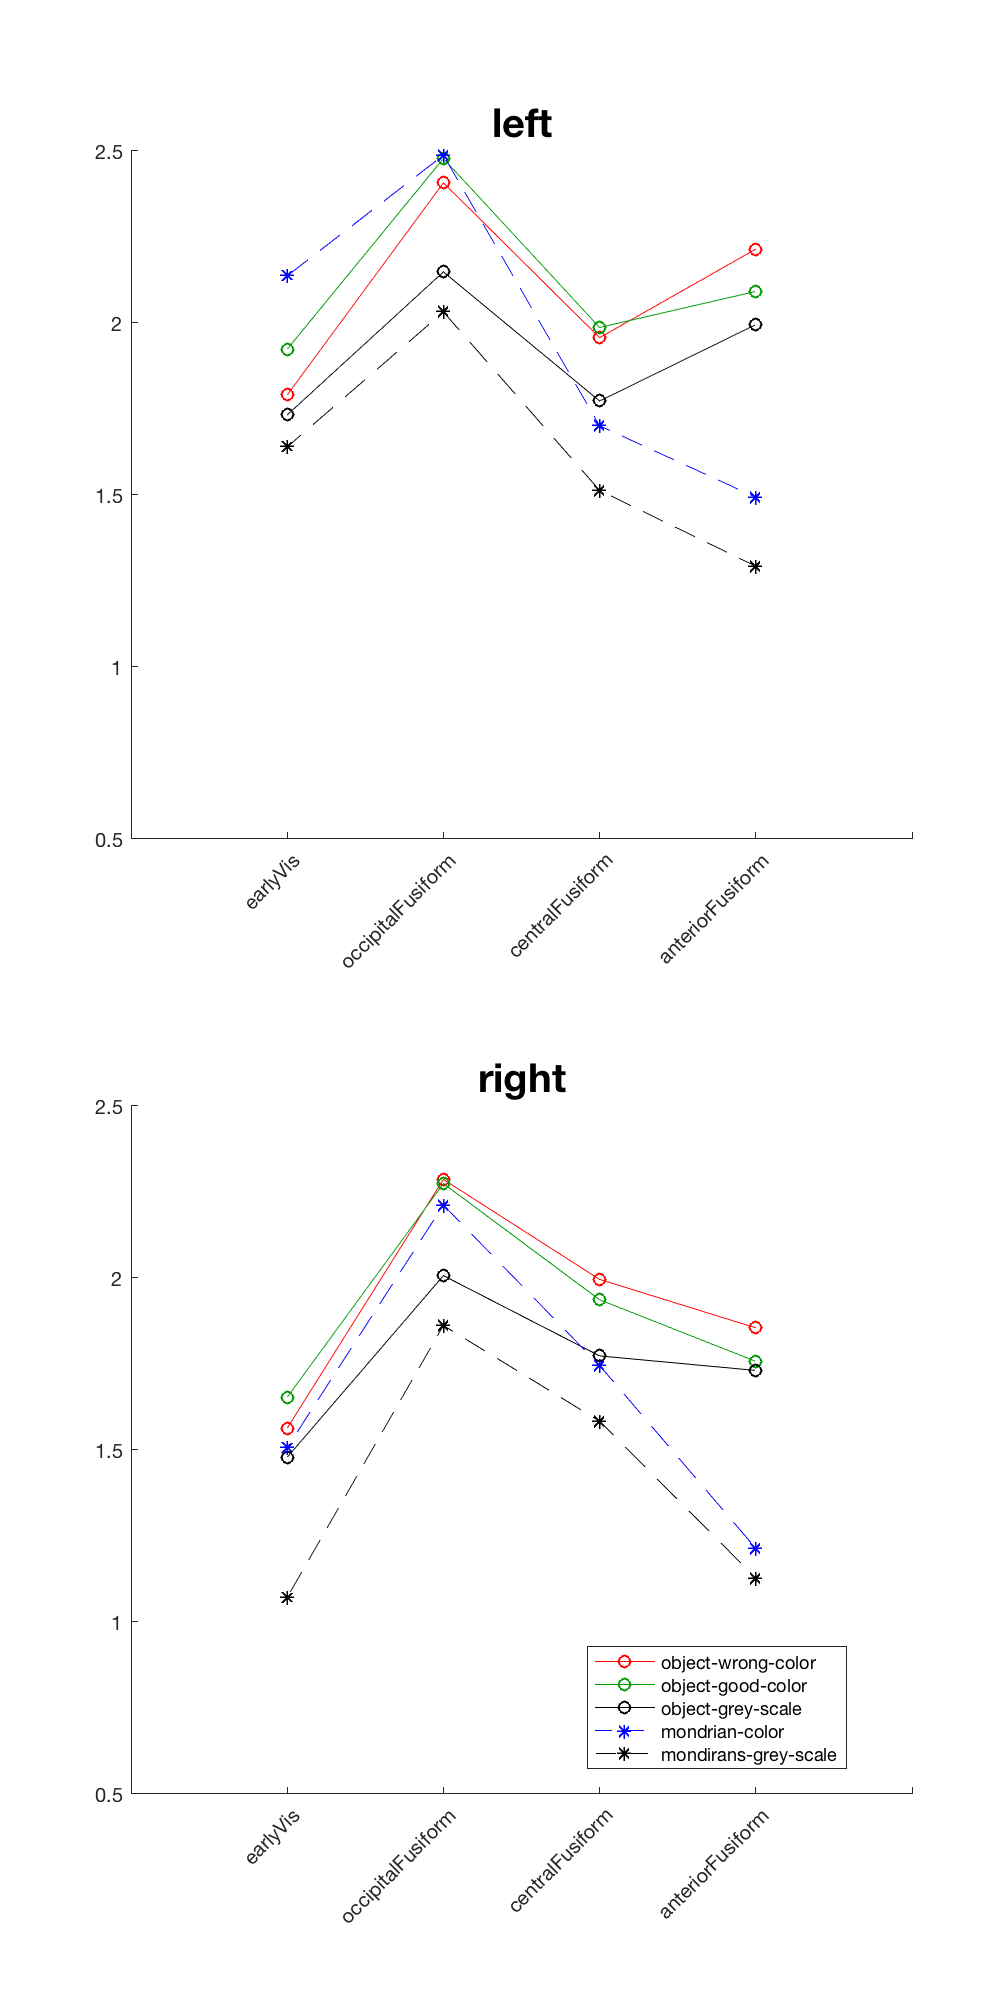


figure('units', 'inches')

Marker = {'-o', '-o', '-o', '--*','--*'};
Color = {'r', [0 153 0]./255, 'k','b', 'k' };

idx = [5 3 4 2 1 10 8 9 7 6];
lgd = {};
for i = 1:height(full_rm2_margmeans)/4
    
    data = full_rm2_margmeans(idx(i):10:end, :);
    data = data([3 4 2 1], :);
    
    if  i<6  
        subplot(2,1,1);
        marker_idx = i;
        
    else
        subplot(2,1,2);
        marker_idx = i-5;
    end
    
    hold on
    plot(data{:,4}, Marker{marker_idx}, 'Color', Color{marker_idx})
%     hold on
%     er = errorbar(data{:,5}, data{:,6}, Marker{marker_idx}, 'Color', Color{marker_idx})
%     er.LineStyle = 'none';
    xlim([0 5]);
    ylim ([0.5 2.5])
    xticks(1:1:5);
    xticklabels(string(data{:,1}));
    xtickangle(45);
    title(string(data.Side(1)), 'fontsize',20)
    hold off
    lgd{end+1} = string(data.Conditions(1));
    
set(gcf,'Units','inches','Position',[0 0 7 14])

end
legend(lgd, 'Location', 'best')

## 2) with ANOVAN


megaTable.subject = [1:20]';
megaTable_long_form_s = stack(megaTable, megaTable.Properties.VariableNames(1:end-1), 'IndexVariableName','Conditions',...
    'NewDataVariableName','Response');

cond_parts = cellfun(@(x) strsplit(x, '_'), string(megaTable_long_form_s.Conditions), 'UniformOutput', 0);

megaTable_long_form_s.ROI = cellfun(@(x) x(1),  cond_parts);
megaTable_long_form_s.Side = cellfun(@(x) x(2),  cond_parts);
megaTable_long_form_s.Conditions =  cellfun(@(x) strjoin(x(3:end),'-'), cond_parts, 'UniformOutput', 0);
megaTable_long_form_s = megaTable_long_form_s(:, [5, 4, 2, 1, 3]);

nested = [0 0 0 0 ; 1 0 0 0; 0 1 0 0; 0 0 0 0];
model = [1 0 0 0 ; 0 1 0 0; 0 0 1 0; 0 1 1 0; 1 1 0 0; 1 1 1 0]

model =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     1     1     0
     1     1     0     0
     1     1     1     0


p =     0.0003
    0.0000
    0.0000
    0.1079
    0.0774
    0.9986


stats = struct with fields:
         source: 'anovan'
          resid: [800×1 double]
         coeffs: [80×1 double]
            Rtr: [36×36 double]
       rowbasis: [40×80 double]
            dfe: 764
            mse: 0.6657
    nullproject: [80×36 double]
          terms: [6×4 double]
        nlevels: [4×1 double]
     continuous: [0 0 0 0]
         vmeans: [4×1 double]
       termcols: [7×1 double]
     coeffnames: {80×1 cell}
           vars: [80×4 double]
       varnames: {4×1 cell}
       grpnames: {4×1 cell}
        vnested: []
            ems: []
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


terms =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     1     1     0
     1     1     0     0
     1     1     1     0


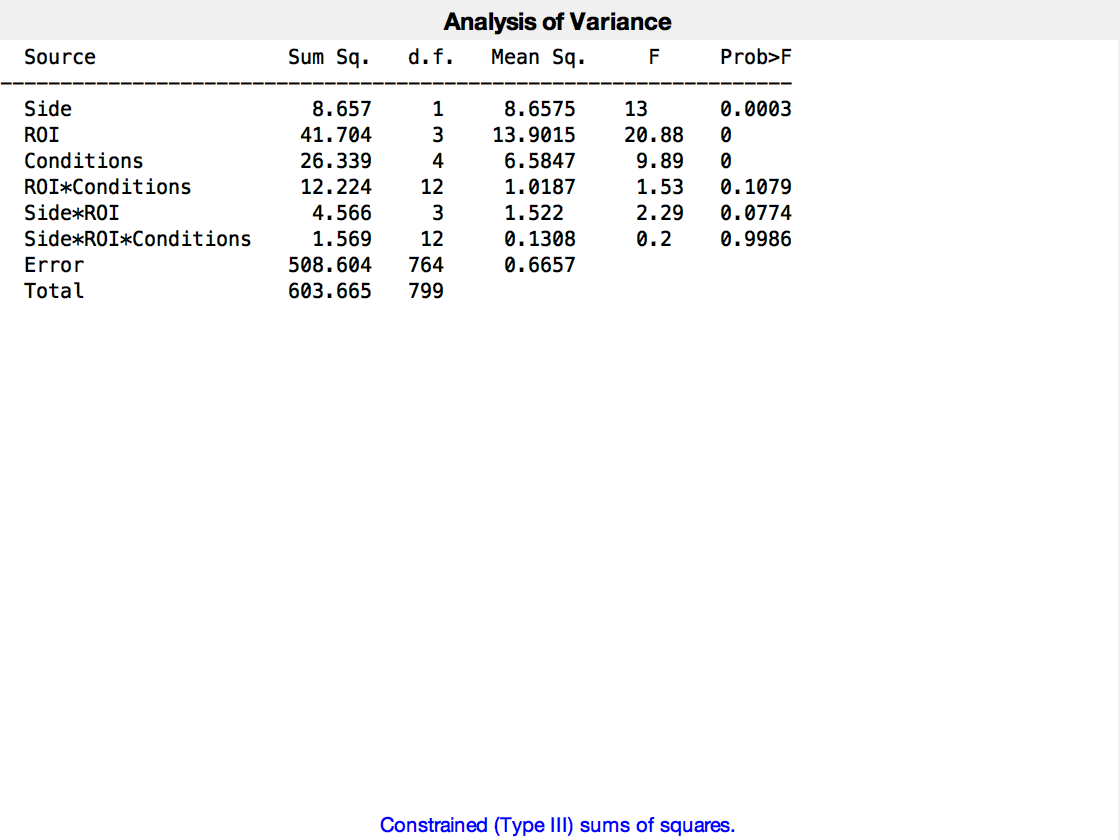


[p,~,stats,terms] = anovan(megaTable_long_form.Response,{megaTable_long_form{:, 1}, megaTable_long_form{:, 2}, ...
    megaTable_long_form{:, 3}, megaTable_long_form{:, 4}}, ...
    'random', [4], 'model',model, ...
    'varnames',megaTable_long_form.Properties.VariableNames(1:4))


dums = dummyvar({categorical(megaTable_long_form_s.Side), categorical(megaTable_long_form_s.ROI),...
    categorical(megaTable_long_form_s.Conditions)});
S = unique(megaTable_long_form_s.Side);
R = unique(megaTable_long_form_s.ROI);
C = unique(megaTable_long_form_s.Conditions);
dums_names = [S;R;C];

dums_tab = array2table(dums, 'VariableNames', strrep(dums_names, '-', '_'));
megaTable_long_form_s_dums = [dums_tab, megaTable_long_form_s(:,4:5 )]

megaTable_long_form_s_dums = 800×13 table
    left    right    anteriorFusiform    centralFusiform    earlyVis    occipitalFusiform    mondirans_grey_scale    mondrian_color    object_good_color    object_grey_scale    object_wrong_color    subject    Response
    ____    _____    ________________    _______________    ________    _________________    ____________________    ______________    _________________    _________________    __________________    _______    ________

    1       0        1                   0                  0           0    

[p,~,stats] = anovan(megaTable_long_form_s_dums.Response, mat2cell(megaTable_long_form_s_dums{:, 1:end-1}, 800, ones(1, 12)),...
    'random', [12], 'model',[1 -1 1 -0.33 -0.33 -0.33 0.5 0.5 -1 -1 1])

Error using anovan>argcheck (line 988)
MODEL is invalid.

Error in anovan (line 164)
[varnames,termlist,randomvar,sstype,continuous,vnested] = argcheck(ng,...




[p,~,stats,terms] = anovan(megaTable_long_form.Response,{megaTable_long_form{:, 1}, megaTable_long_form{:, 2}, ...
    megaTable_long_form{:, 3}, megaTable_long_form{:, 4}}, ...
    'random', [4], 'model',model, ...
    'varnames',megaTable_long_form.Properties.VariableNames(1:4))


## PLANNED COMPARISONS

megaTable_for_contrasts = unstack(megaTable_long_form_s, 'Response', 'Conditions');



%object vs abstract color
 c1 = [1 -1 0.5 -1 0.5]

c1 =     1.0000   -1.0000    0.5000   -1.0000    0.5000


%object vs abstract shape (shape effect)
c2 = [-0.5 -0.5 0.33 0.33 0.33]

c2 =    -0.5000   -0.5000    0.3300    0.3300    0.3300


%congruency effect (good vs bad)
c3 = [0 0 1 0 -1]

c3 =      0     0     1     0    -1


%congruency effect (bad vs good)
c4 = [0 0 -1 0 1]

c4 =      0     0    -1     0     1



% check contrast orthogonality (all sums should = 0)
sum(c1.* c2)

ans = 0

sum(c1.* c3)

ans = 0

sum(c1.* c4)

ans = 0

sum(c2.* c3)

ans = 0

sum(c2.* c4)

ans = 0

sum(c3.* c4)

ans = -2

megaTable_for_contrasts.psi1 = sum(c1.*megaTable_for_contrasts{:, 4:8}, 2);
megaTable_for_contrasts.psi2 = sum(c2.*megaTable_for_contrasts{:, 4:8}, 2);
megaTable_for_contrasts.psi3 = sum(c3.*megaTable_for_contrasts{:, 4:8}, 2);
megaTable_for_contrasts.psi4 = sum(c4.*megaTable_for_contrasts{:, 4:8}, 2);

contrasts_within_factors = unique(megaTable_for_contrasts(:, 1:2), 'stable');
contrasts_within_factors.Side_by_ROI = categorical(contrasts_within_factors.Side).*categorical (contrasts_within_factors.ROI);



%Object-color ANOVA
tmp = unstack (megaTable_for_contrasts(:, [1 2 3 9]), 'psi1', 'ROI');
psi1 = unstack (tmp, tmp.Properties.VariableNames(3:end), 'Side');
psi1.Properties.VariableNames(2:end) = strcat('psi1_', psi1.Properties.VariableNames(2:end));

objectColor_rm = fitrm(psi1,'psi1_anteriorFusiform_left-psi1_occipitalFusiform_right~1',...
    'WithinDesign',contrasts_within_factors)

objectColor_rm =   RepeatedMeasuresModel with properties:

   Between Subjects:
         BetweenDesign: [20×9 table]
         ResponseNames: {'psi1_anteriorFusiform_left'  'psi1_anteriorFusiform_right'  'psi1_centralFusiform_left'  'psi1_centralFusiform_right'  'psi1_earlyVis_left'  'psi1_earlyVis_right'  'psi1_occipitalFusiform_left'  'psi1_occipitalFusiform_right'}
    BetweenFactorNames: {1×0 cell}
          BetweenModel: '1'

   Within Subjects:
          WithinDesign: [8×3 table]
     WithinFactorNames: {'Side'  'ROI'  'Side_by_ROI'}
           WithinModel: 'separatemeans'

   Estimates:
          Coefficients: [1×8 table]
            Covariance: [8×8 table]


objectColor_anova = ranova(objectColor_rm, 'WithinModel','Side*ROI' )

objectColor_anova = 8×8 table
                             SumSq     DF     MeanSq         F        pValue       pValueGG      pValueHF     pValueLB 
                            _______    __    _________    _______    _________    __________    __________    _________

    (Intercept)              2.1568     1       2.1568     2.5664      0.12565       0.12565       0.12565      0.12565
    Error                    15.968    19      0.84043                                                                 
    (Intercept):Side        0.10307     1      0.10307     2.6314      0.12125       0.12125       0.12125      0.12125
    Error(Side)             0

margmean(objectColor_rm, 'ROI')

ans = 4×5 table
            ROI              Mean        StdErr      Lower        Upper  
    ___________________    _________    ________    ________    _________

    'anteriorFusiform'     -0.027069    0.077008    -0.18825      0.13411
    'centralFusiform'       0.020847    0.062495    -0.10996      0.15165
    'earlyVis'              -0.33933     0.11622    -0.58259    -0.096075
    'occipitalFusiform'     -0.11886    0.078355    -0.28286     0.045137


post_hoc_objectColor_anova_ROI = multcompare(objectColor_rm,'ROI');
post_hoc_objectColor_anova_ROI(post_hoc_objectColor_anova_ROI.pValue<0.07, :)

ans = 4×7 table
          ROI_1                 ROI_2           Difference     StdErr      pValue      Lower        Upper  
    __________________    __________________    __________    ________    ________    ________    _________

    'anteriorFusiform'    'earlyVis'             0.31226      0.090924    0.013536    0.056601      0.56793
    'centralFusiform'     'earlyVis'             0.36018      0.099542    0.009069    0.080282      0.64008
    'earlyVis'            'anteriorFusiform'    -0.31226      0.090924    0.013536    -0.56793    -0.056601
    'earlyVis'            'centralFusiform'     -0.36018      0.099542    0.009069    -0.64008    -0.080282


% plot 


data_to_plot = megaTable_for_contrasts(:, 2:8);
[g, i] = findgroups(data_to_plot.ROI);
to_plot = splitapply(@mean, data_to_plot{:,3:end},g);
to_plot = to_plot([3 4 2 1], [5 3 4 2 1])

to_plot =     1.6771    1.7886    1.6058    1.8221    1.3557
    2.3471    2.3764    2.0778    2.3499    1.9471
    1.9766    1.9619    1.7734    1.7236    1.5485
    2.0350    1.9248    1.8633    1.3539    1.2102


figure
h = plot(to_plot )

h =   5×1 Line array:

  Line
  Line
  Line
  Line
  Line


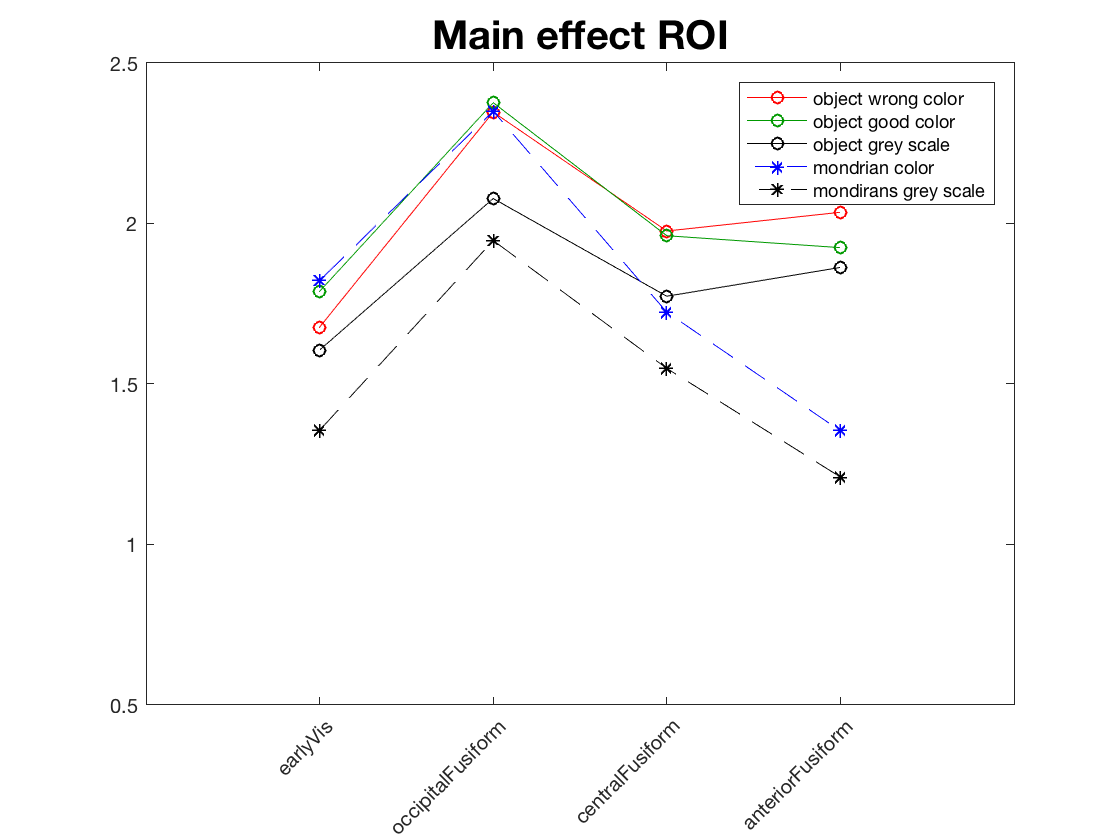


set(h,{'Marker'},{'o';'o';'o'; '*'; '*'})
set(h,{'Color'},{'r'; [0 153 0]./255; 'k';'b'; 'k' })
set(h,{'LineStyle'},{'-';'-';'-'; '--'; '--'})

% hold on
% 
% sem = @(x) std(x)/sqrt(length(x)); %Marcin calculated errors on demeaned data
% to_plot_error = splitapply(sem, data_to_plot{:,3:end},g)
% errorbar(to_plot, to_plot_error, 'k.');
%hold off
%%trick for bars
% ngroups = size(to_plot, 1);
% nbars = size(to_plot, 2)
% 
% 
% % Calculating the width for each bar group
% groupwidth = min(0.8, nbars/(nbars + 1.5));
% for i = 1:nbars
%     x = (1:ngroups) - groupwidth/2 + (2*i-1) * groupwidth / (2*nbars);
%     errorbar(x, to_plot(:,i), to_plot_error(:,i), 'k.');
% end

xlim([0 5]);
    ylim ([0.5 2.5])
    xticks(1:1:5);
    labels = i';
    labels = labels([3 4 2 1]);
    xticklabels(labels);
    xtickangle(45);
    leg = data_to_plot.Properties.VariableNames(3:end);
    leg = strrep (leg, '_', ' ');
    leg = string(leg ([5 3 4 2 1]));
    lgd = legend(leg);
    title('Main effect ROI' , 'fontsize',20)

% Shape anova
tmp = unstack (megaTable_for_contrasts(:, [1 2 3 10]), 'psi2', 'ROI');
psi2 = unstack (tmp, tmp.Properties.VariableNames(3:end), 'Side');
psi2.Properties.VariableNames(2:end) = strcat('psi2_', psi2.Properties.VariableNames(2:end));

shape_rm = fitrm(psi2,'psi2_anteriorFusiform_left-psi2_occipitalFusiform_right~1',...
    'WithinDesign',contrasts_within_factors)

shape_rm =   RepeatedMeasuresModel with properties:

   Between Subjects:
         BetweenDesign: [20×9 table]
         ResponseNames: {'psi2_anteriorFusiform_left'  'psi2_anteriorFusiform_right'  'psi2_centralFusiform_left'  'psi2_centralFusiform_right'  'psi2_earlyVis_left'  'psi2_earlyVis_right'  'psi2_occipitalFusiform_left'  'psi2_occipitalFusiform_right'}
    BetweenFactorNames: {1×0 cell}
          BetweenModel: '1'

   Within Subjects:
          WithinDesign: [8×3 table]
     WithinFactorNames: {'Side'  'ROI'  'Side_by_ROI'}
           WithinModel: 'separatemeans'

   Estimates:
          Coefficients: [1×8 table]
            Covariance: [8×8 table]


shape_anova = ranova(shape_rm, 'WithinModel','Side*ROI' )

shape_anova = 8×8 table
                             SumSq     DF     MeanSq       F         pValue       pValueGG      pValueHF      pValueLB 
                            _______    __    ________    ______    __________    __________    __________    __________

    (Intercept)               11.43     1       11.43    28.094    4.0826e-05    4.0826e-05    4.0826e-05    4.0826e-05
    Error                    7.7301    19     0.40685                                                                  
    (Intercept):Side        0.17584     1     0.17584     2.389       0.13869       0.13869       0.13869       0.13869
    Error(Side)              1.3985

margmean(shape_rm, 'Side_by_ROI')

ans = 8×5 table
          Side_by_ROI            Mean        StdErr       Lower       Upper  
    _______________________    _________    ________    _________    ________

    left anteriorFusiform        0.68651     0.11433      0.44721     0.92581
    left centralFusiform         0.27947    0.050357      0.17407     0.38487
    left earlyVis              -0.090831    0.064904     -0.22668    0.045015
    left occipitalFusiform      0.061353    0.083156     -0.11269      0.2354
    right anteriorFusiform       0.59263      0.1096      0.36323     0.82203
    right centralFusiform        0.21826    0.077904     0.055205     0.38132
    right earlyVis                0.2603    0.069042      0.11579      0.4048
    right occipitalFusiform      0.13052    0.076764    -0.030151     0.29119



post_hoc_shape_anova_Side_x_ROI = multcompare(shape_rm,'Side', 'by', 'ROI');
post_hoc_shape_anova_Side_x_ROI(post_hoc_shape_anova_Side_x_ROI.pValue<0.07, :)

ans = 2×8 table
       ROI        Side_1     Side_2     Difference     StdErr      pValue       Lower       Upper  
    __________    _______    _______    __________    ________    _________    ________    ________

    'earlyVis'    'left'     'right'    -0.35113      0.096157    0.0016969    -0.55239    -0.14987
    'earlyVis'    'right'    'left'      0.35113      0.096157    0.0016969     0.14987     0.55239


post_hoc_shape_anova_Side_x_ROI = multcompare(shape_rm,'ROI','by' , 'Side');
post_hoc_shape_anova_Side_x_ROI(post_hoc_shape_anova_Side_x_ROI.pValue<0.07, :)

ans = 12×8 table
     Side             ROI_1                  ROI_2           Difference     StdErr       pValue       Lower        Upper  
    _______    ___________________    ___________________    __________    ________    __________    ________    _________

    'left'     'anteriorFusiform'     'centralFusiform'       0.40704      0.095508     0.0021845     0.13849       0.6756
    'left'     'anteriorFusiform'     'earlyVis'              0.77734        0.1319    6.1789e-05     0.40645       1.1482
    'left'     'anteriorFusiform'     'occipitalFusiform'     0.62516       0.11719    0.00020477     0.29565      0.95467
    'left'     'centralFusiform'      'anteriorFusiform'     -0.40704      0.095508     0.00218

% plot

data_to_plot = megaTable_for_contrasts(:, 1:8);

[g, i1, i2] = findgroups(data_to_plot.Side, data_to_plot.ROI);
to_plot = splitapply(@mean, data_to_plot{:,4:end},g);
to_plot = to_plot([3 4 2 1 7 8 6 5], [5 3 4 2 1])

to_plot =     1.7907    1.9239    1.7329    2.1372    1.6398
    2.4076    2.4783    2.1486    2.4878    2.0322
    1.9574    1.9870    1.7733    1.7013    1.5134
    2.2148    2.0918    1.9952    1.4935    1.2927
    1.5636    1.6534    1.4788    1.5069    1.0716
    2.2867    2.2746    2.0070    2.2121    1.8619
    1.9959    1.9368    1.7735    1.7458    1.5837
    1.8552    1.7577    1.7313    1.2143    1.1276



leg = data_to_plot.Properties.VariableNames(4:end);
    leg = strrep (leg, '_', ' ');
    leg = string(leg ([5 3 4 2 1]));
    
figure('units', 'inches')
subplot(2, 1 ,1)
    h = plot(to_plot(1:4, :))

h =   5×1 Line array:

  Line
  Line
  Line
  Line
  Line


    
    set(h,{'Marker'},{'o';'o';'o'; '*'; '*'})
    set(h,'MarkerSize',10)
    set(h,{'Color'},{'r'; [0 153 0]./255; 'k';'b'; 'k' })
    set(h,{'LineStyle'},{'-';'-';'-'; '--'; '--'})

    title(i1{1} , 'fontsize',20)
    lgd = legend(leg, 'Location', 'bestoutside');
    xlim([0 5]);
    ylim ([0.5 2.5])
    xticks(1:1:5);
    labels = i2(1:4)';
    labels = labels([3 4 2 1]);
    xticklabels(labels);
    xtickangle(45);
    set(gca, 'FontSize', 15)

subplot (2, 1, 2)
    h = plot(to_plot(5:end, :))

h =   5×1 Line array:

  Line
  Line
  Line
  Line
  Line


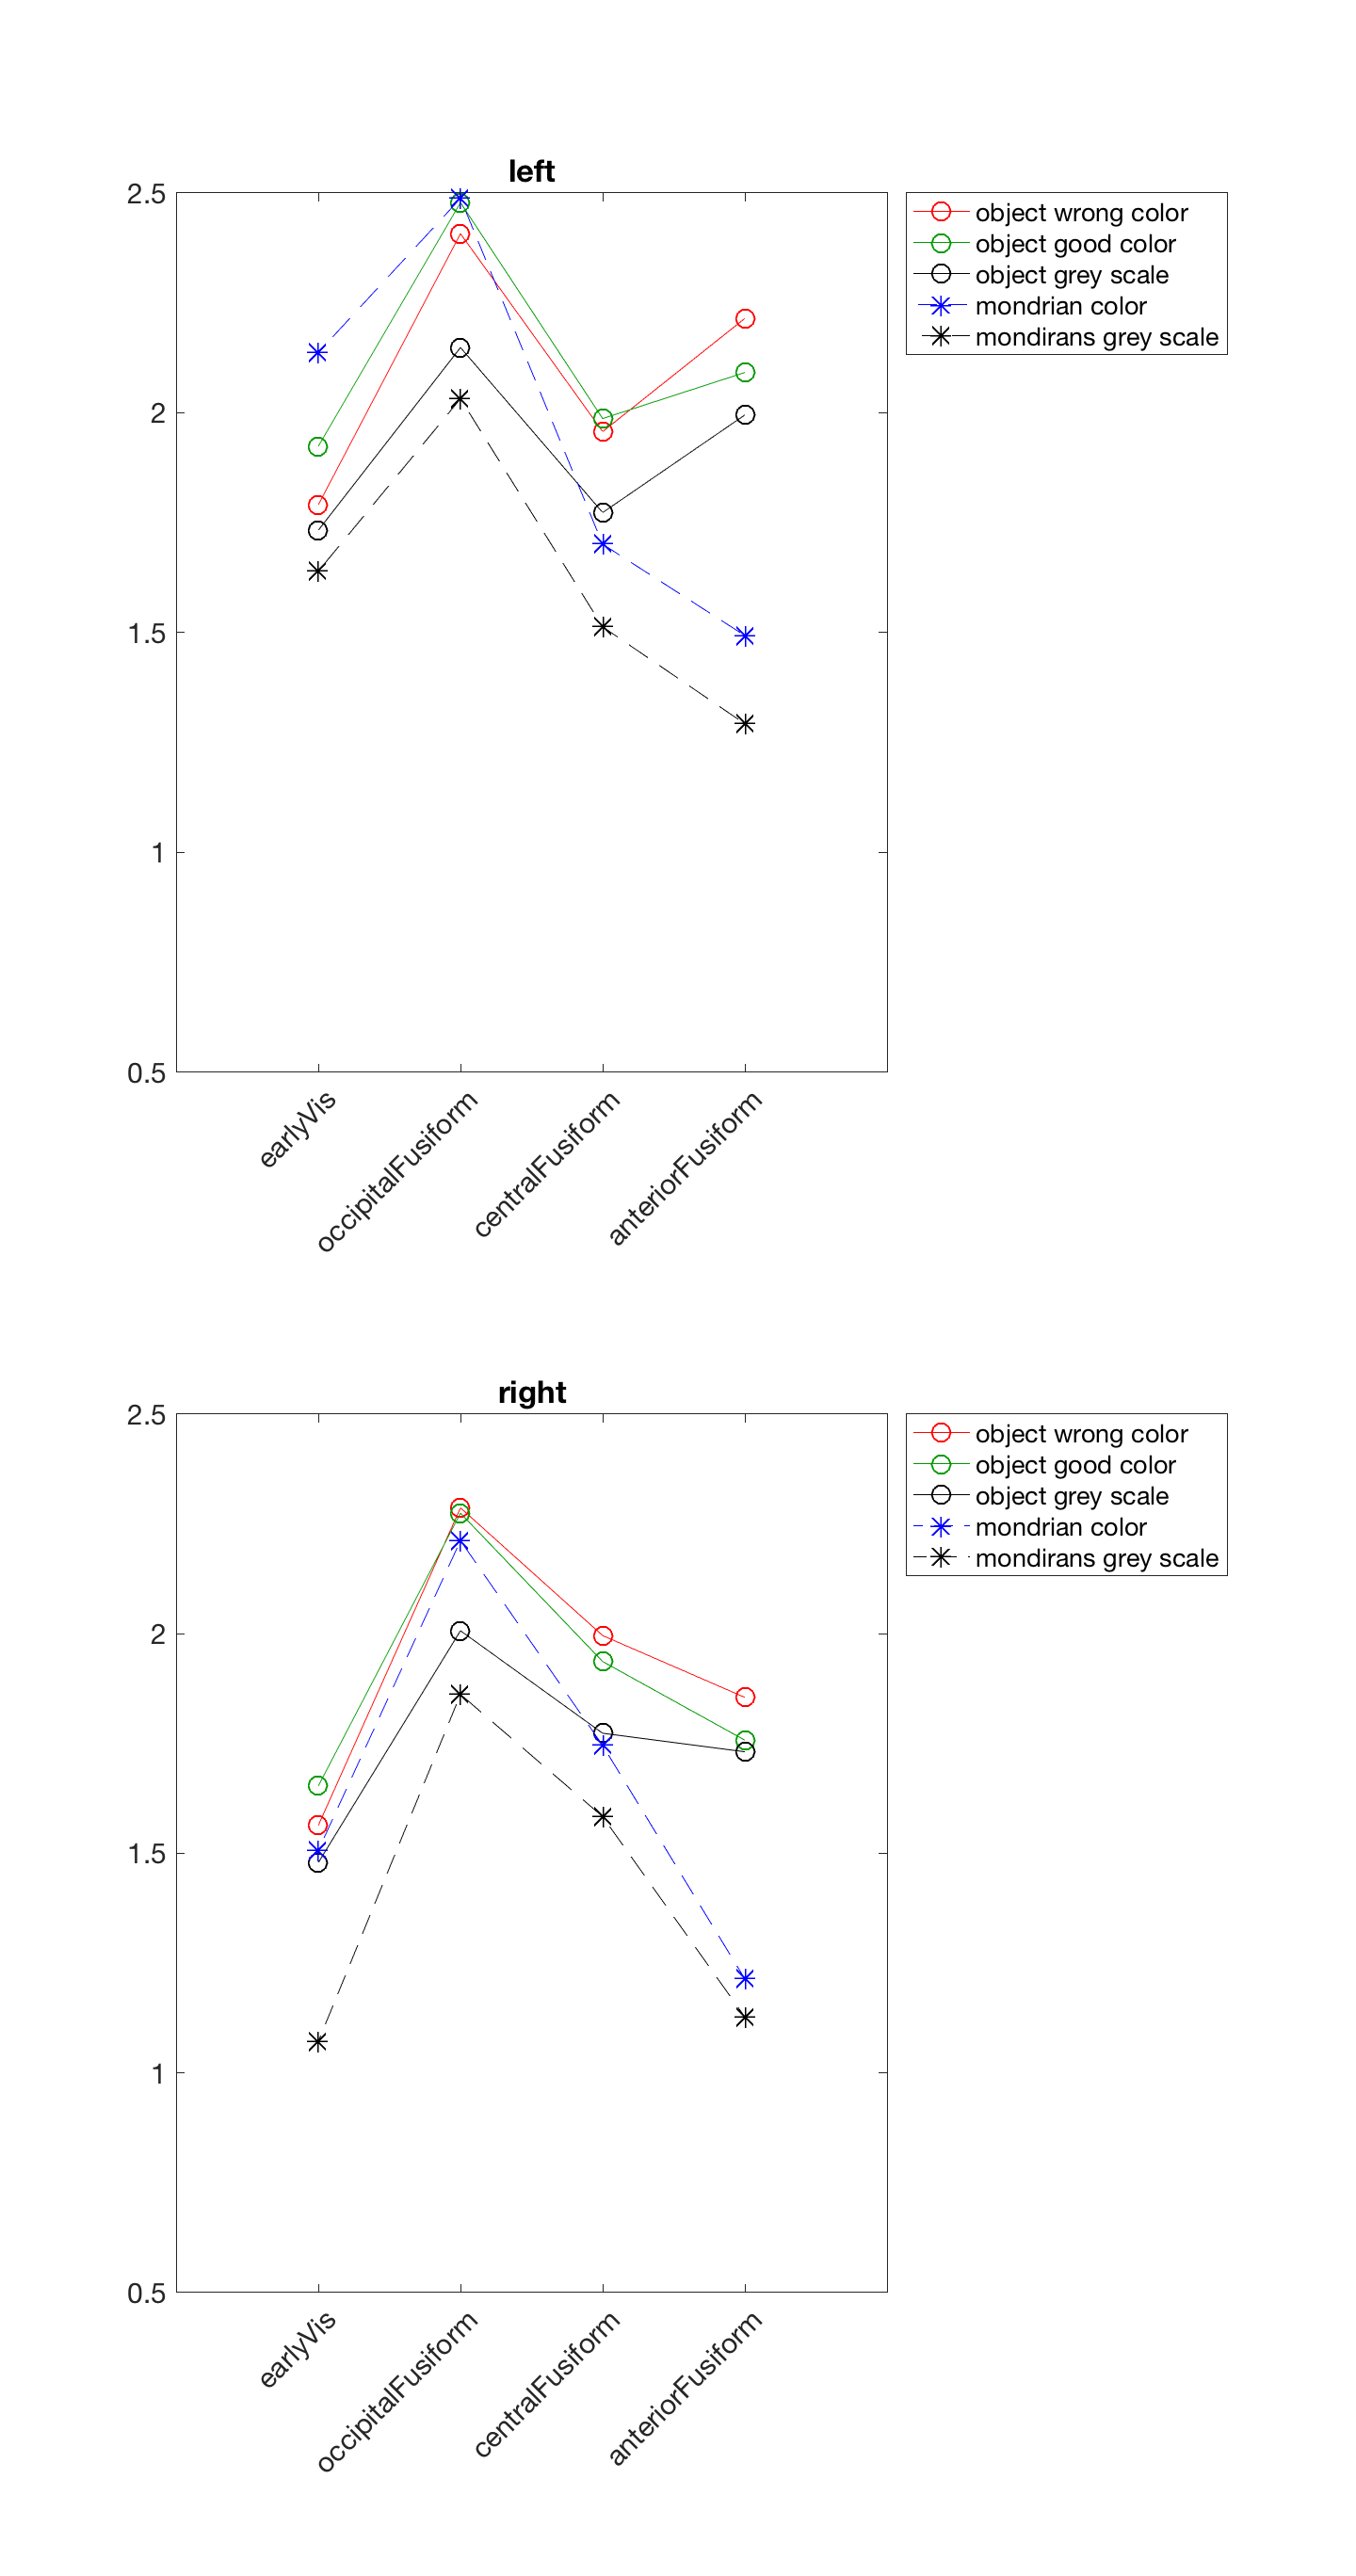


    set(h,{'Marker'},{'o';'o';'o'; '*'; '*'})
    set(h,'MarkerSize',10)
    set(h,{'Color'},{'r'; [0 153 0]./255; 'k';'b'; 'k' })
    set(h,{'LineStyle'},{'-';'-';'-'; '--'; '--'})

    title(i1{5} , 'fontsize',20)
    legend(leg, 'Location', 'bestoutside');
    xlim([0 5]);
    ylim ([0.5 2.5])
    xticks(1:1:5);
    labels = i2(1:4)';
    labels = labels([3 4 2 1]);
    xticklabels(labels);
    xtickangle(45);
    set(gca, 'FontSize', 15)
    
set(gcf,'Units','inches','Position',[0 0 10 19])

%congruency anova (good vs bad color)
tmp = unstack (megaTable_for_contrasts(:, [1 2 3 11]), 'psi3', 'ROI');
psi3 = unstack (tmp, tmp.Properties.VariableNames(3:end), 'Side');
psi3.Properties.VariableNames(2:end) = strcat('psi3_', psi3.Properties.VariableNames(2:end));

congruency_rm = fitrm(psi3,'psi3_anteriorFusiform_left-psi3_occipitalFusiform_right~1',...
    'WithinDesign',contrasts_within_factors)

congruency_rm =   RepeatedMeasuresModel with properties:

   Between Subjects:
         BetweenDesign: [20×9 table]
         ResponseNames: {'psi3_anteriorFusiform_left'  'psi3_anteriorFusiform_right'  'psi3_centralFusiform_left'  'psi3_centralFusiform_right'  'psi3_earlyVis_left'  'psi3_earlyVis_right'  'psi3_occipitalFusiform_left'  'psi3_occipitalFusiform_right'}
    BetweenFactorNames: {1×0 cell}
          BetweenModel: '1'

   Within Subjects:
          WithinDesign: [8×3 table]
     WithinFactorNames: {'Side'  'ROI'  'Side_by_ROI'}
           WithinModel: 'separatemeans'

   Estimates:
          Coefficients: [1×8 table]
            Covariance: [8×8 table]


congruency_anova = ranova(congruency_rm, 'WithinModel','Side*ROI' )

congruency_anova = 8×8 table
                              SumSq      DF     MeanSq         F          pValue      pValueGG      pValueHF     pValueLB
                            _________    __    _________    ________    __________    _________    __________    ________

    (Intercept)             0.0025209     1    0.0025209    0.012593       0.91183      0.91183       0.91183     0.91183
    Error                      3.8033    19      0.20017                                                                 
    (Intercept):Side         0.089598     1     0.089598      4.8918      0.039436     0.039436      0.039436    0.039436
    Error(Side)         

margmean(congruency_rm, 'Side')

ans = 2×5 table
     Side        Mean        StdErr       Lower       Upper  
    _______    _________    ________    _________    ________

    'left'      0.027633     0.03832    -0.052572     0.10784
    'right'    -0.019695    0.035534    -0.094067    0.054678


margmean(congruency_rm, 'ROI')

ans = 4×5 table
            ROI              Mean        StdErr       Lower        Upper  
    ___________________    _________    ________    _________    _________

    'anteriorFusiform'      -0.11022    0.054743      -0.2248    0.0043616
    'centralFusiform'      -0.014743    0.029795    -0.077103     0.047618
    'earlyVis'               0.11152     0.04627     0.014672      0.20836
    'occipitalFusiform'      0.02932    0.047661    -0.070436      0.12908



post_hoc_congruency_anova_Side = multcompare(congruency_rm,'Side');
post_hoc_congruency_anova_Side(post_hoc_congruency_anova_Side.pValue<0.07, :)

ans = 2×7 table
    Side_1     Side_2     Difference     StdErr      pValue       Lower        Upper   
    _______    _______    __________    ________    ________    _________    __________

    'left'     'right'     0.047328     0.021399    0.039436    0.0025402      0.092116
    'right'    'left'     -0.047328     0.021399    0.039436    -0.092116    -0.0025402


post_hoc_congruency_anova_ROI = multcompare(congruency_rm,'ROI');
post_hoc_congruency_anova_ROI(post_hoc_congruency_anova_ROI.pValue<0.07, :)

ans = 4×7 table
          ROI_1                 ROI_2           Difference     StdErr      pValue       Lower        Upper  
    __________________    __________________    __________    ________    _________    ________    _________

    'anteriorFusiform'    'earlyVis'            -0.22173      0.059814    0.0074656    -0.38992    -0.053547
    'centralFusiform'     'earlyVis'            -0.12626      0.034664    0.0086042    -0.22373     -0.02879
    'earlyVis'            'anteriorFusiform'     0.22173      0.059814    0.0074656    0.053547      0.38992
    'earlyVis'            'centralFusiform'      0.12626      0.034664    0.0086042     0.02879      0.22373


data_to_plot = megaTable_for_contrasts(:, [2 6 8]);
[g, i] = findgroups(data_to_plot.ROI);
to_plot = splitapply(@mean, data_to_plot{:,2:end},g);
to_plot = to_plot([3 4 2 1], :)

to_plot =     1.7886    1.6771
    2.3764    2.3471
    1.9619    1.9766
    1.9248    2.0350


figure
h = plot(to_plot )

h =   2×1 Line array:

  Line
  Line


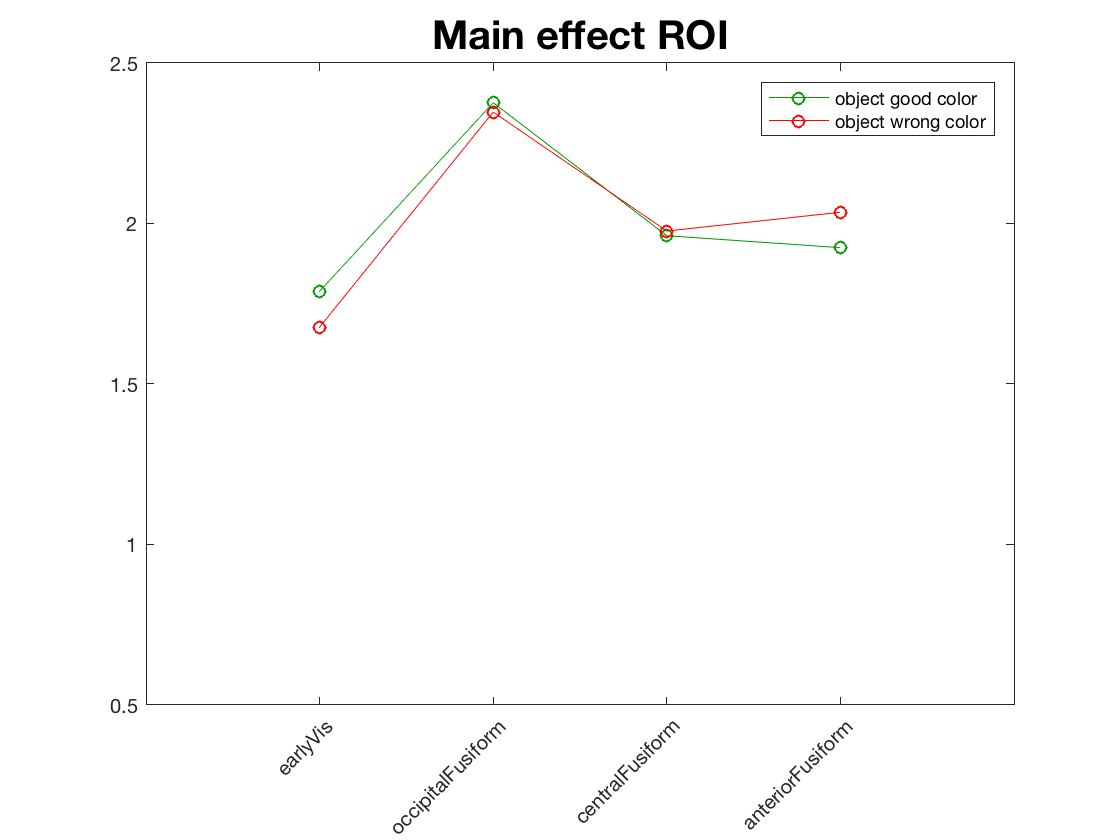


set(h,{'Marker'},{'o';'o'})
set(h,{'Color'},{[0 153 0]./255  ; 'r'})
set(h,{'LineStyle'},{'-';'-'})

xlim([0 5]);
    ylim ([0.5 2.5])
    xticks(1:1:5);
    labels = i';
    labels = labels([3 4 2 1]);
    xticklabels(labels);
    xtickangle(45);
    leg = data_to_plot.Properties.VariableNames(2:end);
    leg = strrep (leg, '_', ' ');
    leg = string(leg );
    lgd = legend(leg);
    title('Main effect ROI' , 'fontsize',20)

%congruency anova2 (bad-good color)

tmp = unstack (megaTable_for_contrasts(:, [1 2 3 12]), 'psi4', 'ROI');
psi4 = unstack (tmp, tmp.Properties.VariableNames(3:end), 'Side');
psi4.Properties.VariableNames(2:end) = strcat('psi4_', psi4.Properties.VariableNames(2:end));

congruency_rm2 = fitrm(psi4,'psi4_anteriorFusiform_left-psi4_occipitalFusiform_right~1',...
    'WithinDesign',contrasts_within_factors)

congruency_rm2 =   RepeatedMeasuresModel with properties:

   Between Subjects:
         BetweenDesign: [20×9 table]
         ResponseNames: {'psi4_anteriorFusiform_left'  'psi4_anteriorFusiform_right'  'psi4_centralFusiform_left'  'psi4_centralFusiform_right'  'psi4_earlyVis_left'  'psi4_earlyVis_right'  'psi4_occipitalFusiform_left'  'psi4_occipitalFusiform_right'}
    BetweenFactorNames: {1×0 cell}
          BetweenModel: '1'

   Within Subjects:
          WithinDesign: [8×3 table]
     WithinFactorNames: {'Side'  'ROI'  'Side_by_ROI'}
           WithinModel: 'separatemeans'

   Estimates:
          Coefficients: [1×8 table]
            Covariance: [8×8 table]


congruency_anova2 = ranova(congruency_rm2, 'WithinModel','Side*ROI' )

congruency_anova2 = 8×8 table
                              SumSq      DF     MeanSq         F          pValue      pValueGG      pValueHF     pValueLB
                            _________    __    _________    ________    __________    _________    __________    ________

    (Intercept)             0.0025209     1    0.0025209    0.012593       0.91183      0.91183       0.91183     0.91183
    Error                      3.8033    19      0.20017                                                                 
    (Intercept):Side         0.089598     1     0.089598      4.8918      0.039436     0.039436      0.039436    0.039436
    Error(Side)         

margmean(congruency_rm2, 'Side')

ans = 2×5 table
     Side        Mean        StdErr       Lower       Upper  
    _______    _________    ________    _________    ________

    'left'     -0.027633     0.03832     -0.10784    0.052572
    'right'     0.019695    0.035534    -0.054678    0.094067


margmean(congruency_rm2, 'ROI')

ans = 4×5 table
            ROI              Mean       StdErr       Lower         Upper  
    ___________________    ________    ________    __________    _________

    'anteriorFusiform'      0.11022    0.054743    -0.0043616       0.2248
    'centralFusiform'      0.014743    0.029795     -0.047618     0.077103
    'earlyVis'             -0.11152     0.04627      -0.20836    -0.014672
    'occipitalFusiform'    -0.02932    0.047661      -0.12908     0.070436



post_hoc_congruency_anova2_Side = multcompare(congruency_rm2,'Side');
post_hoc_congruency_anova2_Side(post_hoc_congruency_anova2_Side.pValue<0.07, :)

ans = 2×7 table
    Side_1     Side_2     Difference     StdErr      pValue       Lower        Upper   
    _______    _______    __________    ________    ________    _________    __________

    'left'     'right'    -0.047328     0.021399    0.039436    -0.092116    -0.0025402
    'right'    'left'      0.047328     0.021399    0.039436    0.0025402      0.092116


post_hoc_congruency_anova2_ROI = multcompare(congruency_rm2,'ROI');
post_hoc_congruency_anova2_ROI(post_hoc_congruency_anova2_ROI.pValue<0.07, :)

ans = 4×7 table
          ROI_1                 ROI_2           Difference     StdErr      pValue       Lower        Upper  
    __________________    __________________    __________    ________    _________    ________    _________

    'anteriorFusiform'    'earlyVis'             0.22173      0.059814    0.0074656    0.053547      0.38992
    'centralFusiform'     'earlyVis'             0.12626      0.034664    0.0086042     0.02879      0.22373
    'earlyVis'            'anteriorFusiform'    -0.22173      0.059814    0.0074656    -0.38992    -0.053547
    'earlyVis'            'centralFusiform'     -0.12626      0.034664    0.0086042    -0.22373     -0.02879


    %congruency anova abs(good-bad color): the regions that are able to differentiate

    
megaTable_for_contrasts.absCongr = abs(megaTable_for_contrasts.object_good_color-megaTable_for_contrasts.object_wrong_color);    
tmp = unstack (megaTable_for_contrasts(:, [1 2 3 12]), 'absCongr', 'ROI');
absCongr = unstack (tmp, tmp.Properties.VariableNames(3:end), 'Side');
absCongr.Properties.VariableNames(2:end) = strcat('absCongr_', absCongr.Properties.VariableNames(2:end));

abcCongruency_rm = fitrm(absCongr,'absCongr_anteriorFusiform_left-absCongr_occipitalFusiform_right~1',...
    'WithinDesign',contrasts_within_factors)

abcCongruency_rm =   RepeatedMeasuresModel with properties:

   Between Subjects:
         BetweenDesign: [20×9 table]
         ResponseNames: {1×8 cell}
    BetweenFactorNames: {1×0 cell}
          BetweenModel: '1'

   Within Subjects:
          WithinDesign: [8×3 table]
     WithinFactorNames: {'Side'  'ROI'  'Side_by_ROI'}
           WithinModel: 'separatemeans'

   Estimates:
          Coefficients: [1×8 table]
            Covariance: [8×8 table]


absCongruency_anova = ranova(abcCongruency_rm, 'WithinModel','Side*ROI' )

absCongruency_anova = 8×8 table
                             SumSq      DF     MeanSq       F         pValue       pValueGG      pValueHF      pValueLB 
                            ________    __    ________    ______    __________    __________    __________    __________

    (Intercept)               5.3067     1      5.3067    85.089    1.9007e-08    1.9007e-08    1.9007e-08    1.9007e-08
    Error                      1.185    19    0.062366                                                                  
    (Intercept):Side        0.039584     1    0.039584    2.5317       0.12808       0.12808       0.12808       0.12808
    Error(Side)         

margmean(abcCongruency_rm, 'ROI')

ans = 4×5 table
            ROI             Mean       StdErr      Lower      Upper 
    ___________________    _______    ________    _______    _______

    'anteriorFusiform'     0.21964     0.03461    0.14721    0.29208
    'centralFusiform'       0.1393    0.013782    0.11046    0.16815
    'earlyVis'             0.19559    0.029182    0.13451    0.25667
    'occipitalFusiform'    0.17393    0.027867    0.11561    0.23226


post_hoc_absCongruency_anova_ROI = multcompare(abcCongruency_rm,'ROI')

post_hoc_absCongruency_anova_ROI = 12×7 table
           ROI_1                  ROI_2           Difference     StdErr     pValue       Lower       Upper  
    ___________________    ___________________    __________    ________    _______    _________    ________

    'anteriorFusiform'     'centralFusiform'       0.080341     0.033064    0.10507     -0.01263     0.17331
    'anteriorFusiform'     'earlyVis'              0.024052     0.037145    0.91511    -0.080392      0.1285
    'anteriorFusiform'     'occipitalFusiform'     0.045711     0.028308    0.39433    -0.033886     0.12531
    'centralFusiform'      'anteriorFusiform'     -0.080341     0.033064    0.10507     -0.17331     0.01263
    'centralFusiform'      'earlyVis'             -0.056289  


post_hoc_absCongruency_anova_ROI(post_hoc_absCongruency_anova_ROI.pValue<0.07, :)


ans =

  0×7 empty table



post_hoc_absCongruency_anova_Side_by_ROI = multcompare(abcCongruency_rm,'Side','by' , 'ROI');
post_hoc_absCongruency_anova_Side_by_ROI(post_hoc_absCongruency_anova_Side_by_ROI.pValue<0.07, :)

ans = 2×8 table
            ROI            Side_1     Side_2     Difference     StdErr      pValue       Lower        Upper   
    ___________________    _______    _______    __________    ________    ________    _________    __________

    'occipitalFusiform'    'left'     'right'     0.093212     0.043731    0.046322    0.0016833       0.18474
    'occipitalFusiform'    'right'    'left'     -0.093212     0.043731    0.046322     -0.18474    -0.0016833


% plot
data_to_plot = megaTable_for_contrasts(:, [1 2 12]);
[g, i1, i2] = findgroups(data_to_plot.Side, data_to_plot.ROI);
to_plot = splitapply(@mean, data_to_plot{:,3},g);

to_plot = to_plot([3 4 2 1 7 8 6 5], :)

to_plot =     0.1963
    0.2205
    0.1481
    0.2264
    0.1948
    0.1273
    0.1305
    0.2129


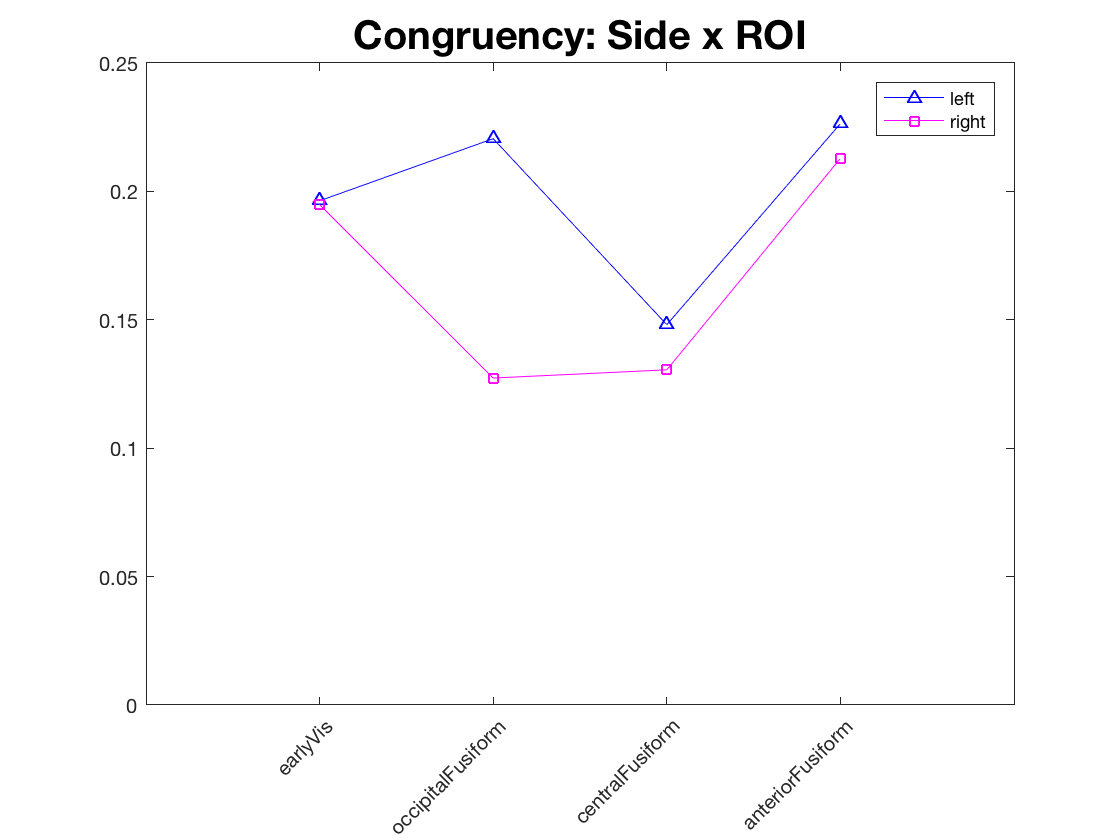


figure
plot(to_plot(1:4), 'b-^')

hold on
plot(to_plot(5:end), 'm-s')

hold off

xlim([0 5]);
    ylim ([0 0.25])
    xticks(1:1:5);
    labels = i2';
    labels = labels([3 4 2 1]);
    xticklabels(labels);
    xtickangle(45);
    lgd = legend('left', 'right');
    title('Congruency: Side x ROI' , 'fontsize',20)